# Regression Assignment Live Script (Part 1 - Grid Partitioning)

### Initialization

clear; clc; close all

## Load, Split and Preprocess Data

data = load('airfoil_self_noise.dat');
[trnData, chkData, tstData] = partition_scale(data, 'MinMaxDiff');

## Define Models

#### TSK 1

tsk1_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 2, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'constant');
tsk1_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk1_genfisOptions);
tsk1_anfisOptions = anfisOptions('InitialFIS', tsk1_initFIS, ...
                'EpochNumber', 300, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

#### TSK-2

tsk2_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 3, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'constant');
tsk2_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk2_genfisOptions);
tsk2_anfisOptions = anfisOptions('InitialFIS', tsk2_initFIS, ...
                'EpochNumber', 200, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);
            

#### TSK-3

tsk3_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 2, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'linear');
tsk3_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk3_genfisOptions);
tsk3_anfisOptions = anfisOptions('InitialFIS', tsk3_initFIS, ...
                'EpochNumber', 300, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

#### TSK-4

tsk4_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 3, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'linear');
tsk4_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk4_genfisOptions);
tsk4_anfisOptions = anfisOptions('InitialFIS', tsk4_initFIS, ...
                'EpochNumber', 100, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

### Train Models

#### Train TSK 1

[tsk1_trnFIS, tsk1_trnError, ~, tsk1_valFIS, tsk1_valError]=anfis(trnData, tsk1_anfisOptions);

#### Train TSK 2

[tsk2_trnFIS, tsk2_trnError, ~, tsk2_valFIS, tsk2_valError]=anfis(trnData, tsk2_anfisOptions);

#### Train TSK 3

[tsk3_trnFIS, tsk3_trnError, ~, tsk3_valFIS, tsk3_valError]=anfis(trnData, tsk3_anfisOptions);

#### Train TSK 4

[tsk4_trnFIS, tsk4_trnError, ~, tsk4_valFIS, tsk4_valError]=anfis(trnData, tsk4_anfisOptions);

## Benchmarking and Graphing

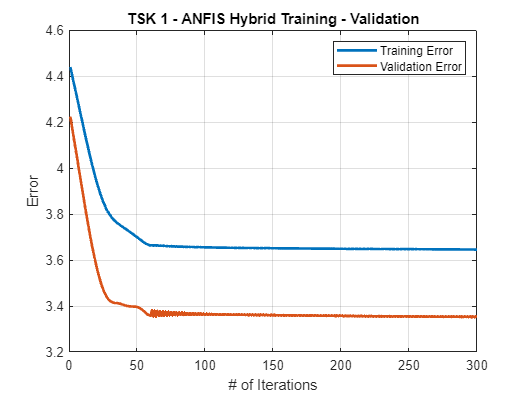

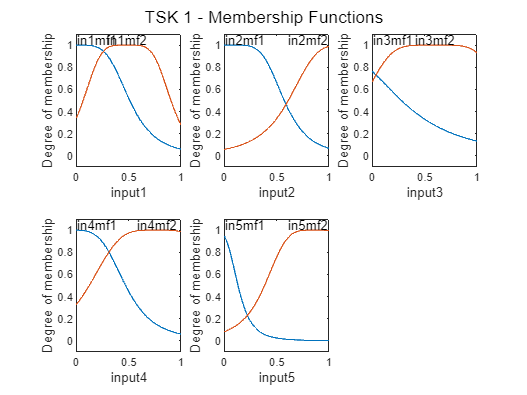

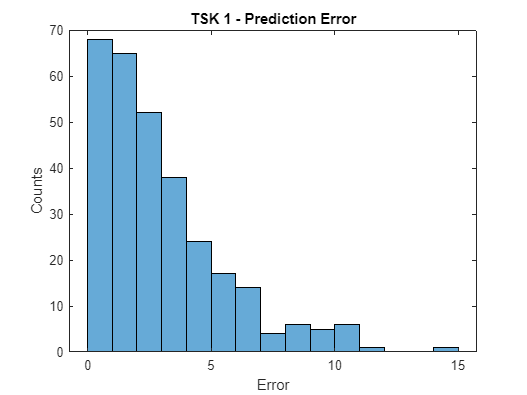

performanceStats = zeros(4,4);

%TSK-1
[RMSE, R2, NMSE, NDEI] = stats_graphs(1, tsk1_valFIS, chkData, tstData, tsk1_trnError, tsk1_valError, 1);

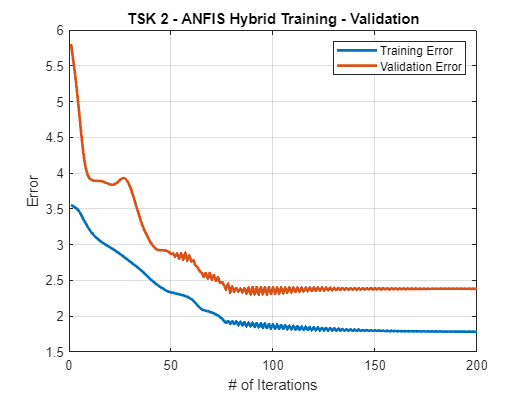

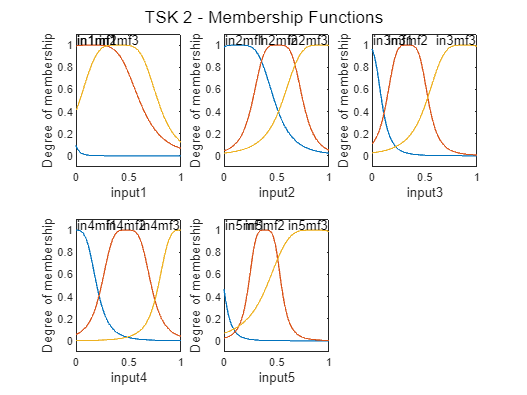

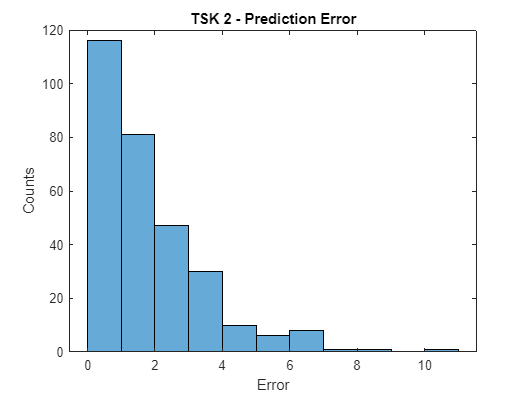

performanceStats(1,:) = [RMSE, R2, NMSE, NDEI];

%TSK-2
[RMSE, R2, NMSE, NDEI] = stats_graphs(2, tsk2_valFIS, chkData, tstData, tsk2_trnError, tsk2_valError, 1);

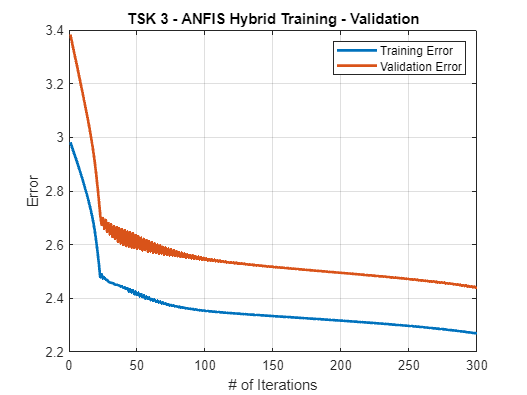

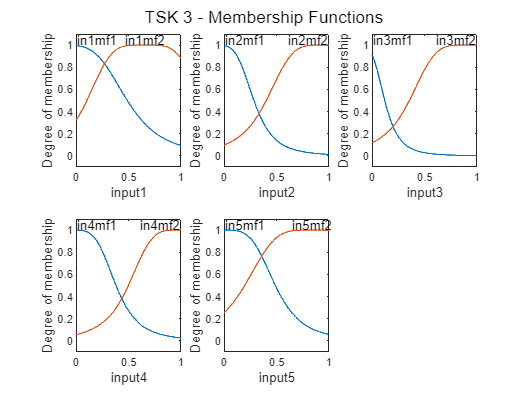

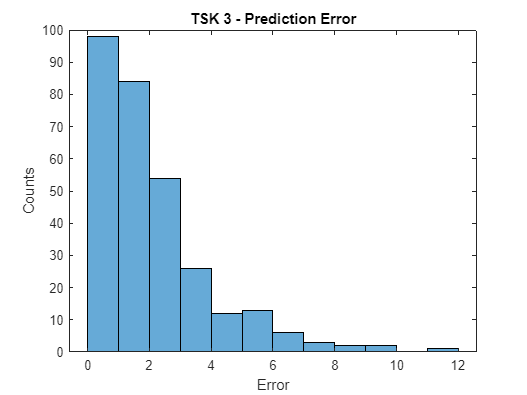

performanceStats(2,:) = [RMSE, R2, NMSE, NDEI];

%TSK-3
[RMSE, R2, NMSE, NDEI] = stats_graphs(3, tsk3_valFIS, chkData, tstData, tsk3_trnError, tsk3_valError, 1);

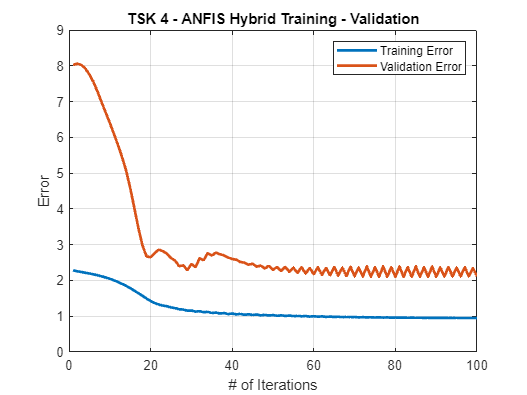

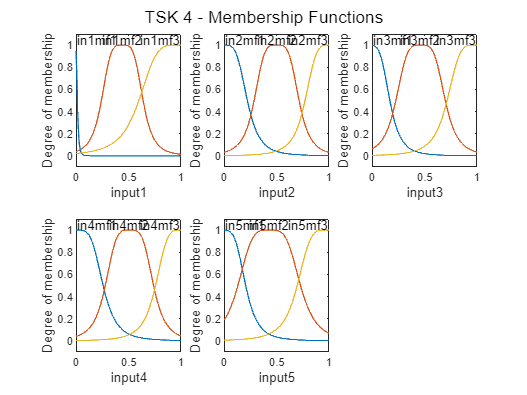

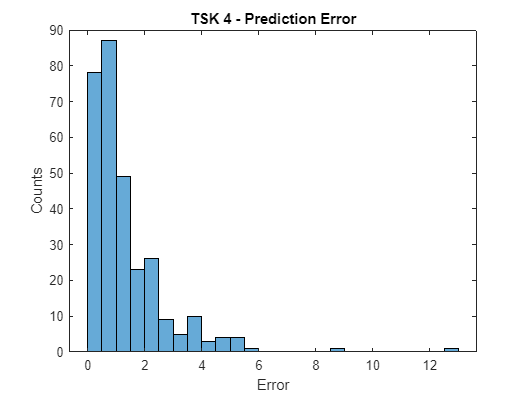

performanceStats(3,:) = [RMSE, R2, NMSE, NDEI];

%TSK-4
[RMSE, R2, NMSE, NDEI] = stats_graphs(4, tsk4_valFIS, chkData, tstData, tsk4_trnError, tsk4_valError, 1);

performanceStats(4,:) = [RMSE, R2, NMSE, NDEI];

%% Form Results Table
colNames = {'RMSE','R2','NMSE','NDEI'};
rowNames = {'TSK-1','TSK-2','TSK-3','TSK-4'};
performanceStats = array2table(performanceStats,'VariableNames',colNames,'RowNames',rowNames);